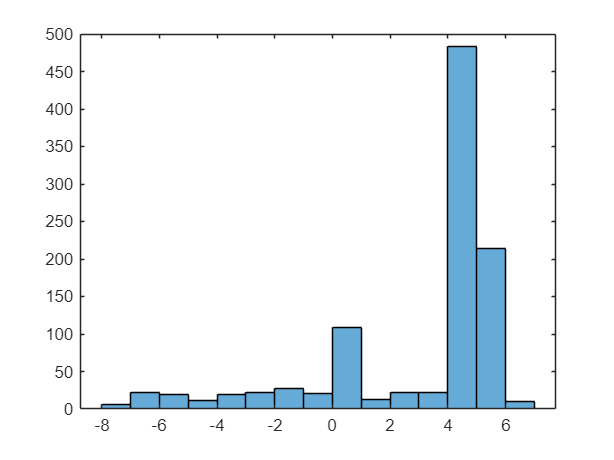

hu =   Histogram - 属性:

             Data: [32×32 single]
           Values: [6 22 20 12 19 22 28 21 109 13 22 22 484 214 10]
          NumBins: 15
         BinEdges: [-8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7]
         BinWidth: 1
        BinLimits: [-8 7]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性


clear
% PIVlab で出力した mat 形式のベクトルデータを読み込み
% ファイルをインポート
fname = 'size1616.mat';
newData1 = load('-mat', fname);
% これらのフィールドから、ベース ワークスペース内に新規変数を作成します。
vars = fieldnames(newData1);
for i = 1:length(vars)
assignin('base', vars{i}, newData1.(vars{i}));
end
% データの確認
u_original = fillmissing(u_original, "constant", 0);
v_original = fillmissing(v_original, "constant", 0);
hu = histogram(u_original)

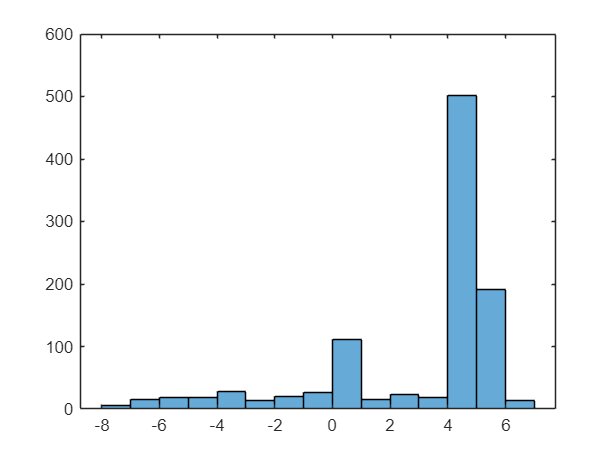

hv =   Histogram - 属性:

             Data: [32×32 single]
           Values: [5 16 19 18 28 14 20 27 112 16 24 19 501 191 14]
          NumBins: 15
         BinEdges: [-8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7]
         BinWidth: 1
        BinLimits: [-8 7]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  显示 所有属性


hv = histogram(v_original)

% 誤差の評価
% 速度はベクトルであるため誤差の評価には誤差ノルムを用いる
% 速度2 成分の誤差ノルムは以下の式で求められる
% N
% En = sqrt ( Σ { (ui‐ustd)^2 + (vi‐vstd)^2 } / 2N )
% i=1
% 基準となる速度（真の値）
ustd = 5;
vstd = 5;
eu = (ustd - u_original).^2;
ev = (vstd - v_original).^2;
euSum = sum(eu, 'all');
evSum = sum(ev, 'all');
N = numel(eu);
En = sqrt( (euSum+evSum) / (2*N) )

En = single
3.7401